# Robotics 2 - Final exam - June 6, 2017 

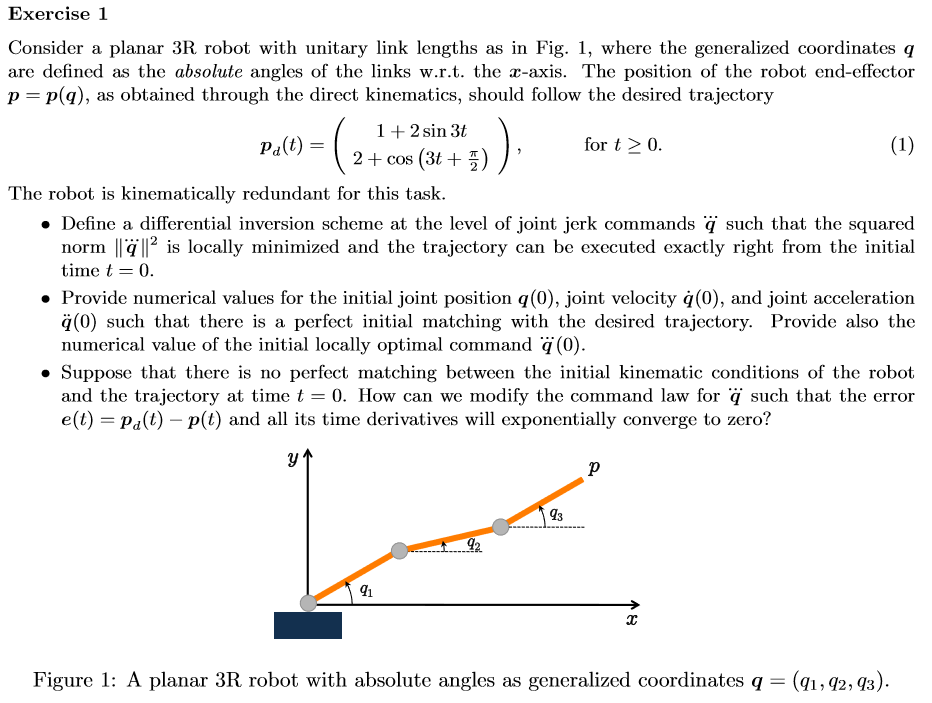

clear;clc
sigma = [0;0;0] % 0: Revolute, 1: Prismatic

sigma =      0
     0
     0


n = length(sigma); %Number of joints

q = sym('q', [n 1]);
qd = sym('qd',[n 1]);
qdd = sym('qdd',[n 1]);
d = sym('d', [n 1]);
a = sym('a', [n 1]);
l = sym('l',[n 1]);
d = sym('d',[n 1]);
m = sym('m',[n 1]);
I = sym('I',[n 1]);
syms g0
g = [0 -g0 0].' 

$$g = \left(\begin{array}{c} 0\\ -g_{0}\\ 0 \end{array}\right)$$


% alpha,a, d, theta
% Absolute coordinates 
dhTable = [0 l(1) 0 q(1);
           0 l(2) 0 q(2)-q(1);
           0 l(3) 0 q(3)-q(2);]

$$dhTable = \left(\begin{array}{cccc} 0 & l_{1} & 0 & q_{1}\\ 0 & l_{2} & 0 & q_{2}-q_{1}\\ 0 & l_{3} & 0 & q_{3}-q_{2} \end{array}\right)$$


% Relative coordinates (normal configuration)
% dhTable = [0 l(1) 0 q(1);
%            0 l(2) 0 q(2);
%            0 l(3) 0 q(3);]


%dhTable = subs(dhTable,l,ones([n 1]))     % Unitary links

[Ttotal, TPartial] = getTransformationMatrix(subs(dhTable,l,ones([n 1])),'alpha') % Unitary links in dhTable

$$Ttotal = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & \cos\left(q_{1}\right)+\cos\left(q_{2}\right)+\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & \sin\left(q_{1}\right)+\sin\left(q_{2}\right)+\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TPartial = 1×3 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}


% Script to create time dependent variables
var_ind = 't';
var_dep = 'q';
var_set =[]


var_set =

     []



syms(var_ind)
for i=1:n
   var_dep_str = strcat(var_dep,num2str(i),'(',var_ind,')');
   syms(var_dep_str);
   var_set = [var_set; str2sym(var_dep_str)]; % appends the variable to the set
end

qt = var_set

$$qt = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right) \end{array}\right)$$

qdt = diff(qt,t)

$$qdt = \left(\begin{array}{c} \frac{\partial }{\partial t}q_{1}\left(t\right)\\ \frac{\partial }{\partial t}q_{2}\left(t\right)\\ \frac{\partial }{\partial t}q_{3}\left(t\right) \end{array}\right)$$

qddt = diff(diff(qt,t))

$$qddt = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}q_{3}\left(t\right) \end{array}\right)$$

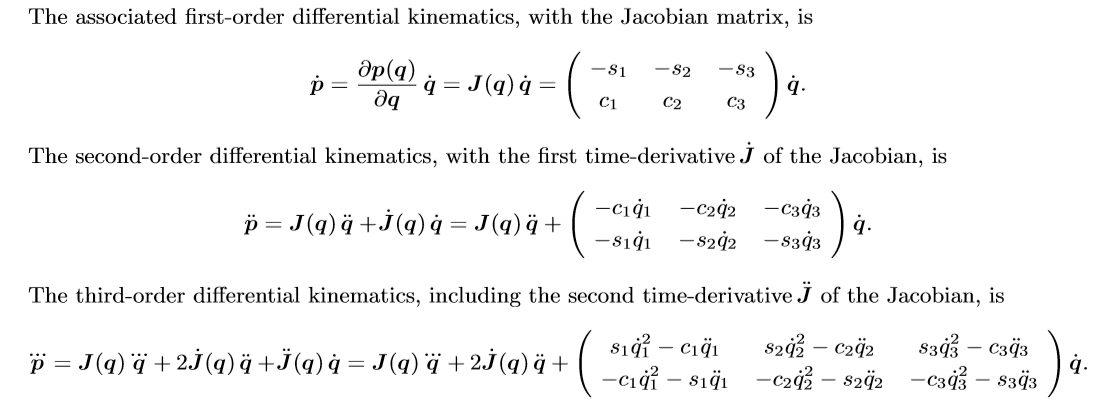

p = Ttotal(1:2,4)

$$p = \left(\begin{array}{c} \cos\left(q_{1}\right)+\cos\left(q_{2}\right)+\cos\left(q_{3}\right)\\ \sin\left(q_{1}\right)+\sin\left(q_{2}\right)+\sin\left(q_{3}\right) \end{array}\right)$$

J = jacobian(p,q)

$$J = \left(\begin{array}{ccc} -\sin\left(q_{1}\right) & -\sin\left(q_{2}\right) & -\sin\left(q_{3}\right)\\ \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) \end{array}\right)$$

J = subs(J,q,qt)

$$J = \left(\begin{array}{ccc} -\sin\left(q_{1}\left(t\right)\right) & -\sin\left(q_{2}\left(t\right)\right) & -\sin\left(q_{3}\left(t\right)\right)\\ \cos\left(q_{1}\left(t\right)\right) & \cos\left(q_{2}\left(t\right)\right) & \cos\left(q_{3}\left(t\right)\right) \end{array}\right)$$

% Jacobian derivates, wrt time
Jd = diff(J,t)

$$Jd = \left(\begin{array}{ccc} -\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) & -\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & -\cos\left(q_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right)\\ -\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) & -\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right) & -\sin\left(q_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{3}\left(t\right) \end{array}\right)$$

Jdd = diff(Jd,t)

$$Jdd = \begin{array}{l} \left(\begin{array}{ccc} \sin\left(q_{1}\left(t\right)\right)\,\sigma_{3}-\cos\left(q_{1}\left(t\right)\right)\,\sigma_{6} & \sin\left(q_{2}\left(t\right)\right)\,\sigma_{2}-\cos\left(q_{2}\left(t\right)\right)\,\sigma_{5} & \sin\left(q_{3}\left(t\right)\right)\,\sigma_{1}-\cos\left(q_{3}\left(t\right)\right)\,\sigma_{4}\\ -\sin\left(q_{1}\left(t\right)\right)\,\sigma_{6}-\cos\left(q_{1}\left(t\right)\right)\,\sigma_{3} & -\sin\left(q_{2}\left(t\right)\right)\,\sigma_{5}-\cos\left(q_{2}\left(t\right)\right)\,\sigma_{2} & -\sin\left(q_{3}\left(t\right)\right)\,\sigma_{4}-\cos\left(q_{3}\left(t\right)\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{3}\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}\\ \sigma_{3}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{4}=\frac{\partial^{2}}{\partial t^{2}}q_{3}\left(t\right)\\ \sigma_{5}=\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)\\ \sigma_{6}=\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right) \end{array}$$

Jdd1 = subs(Jdd,diff(diff(qt)),qdd);
Jdd1 = subs(Jdd1,diff(qt),qd);
Jdd1 = subs(Jdd1,qt,q)

$$Jdd1 = \left(\begin{array}{ccc} {{\mathrm{qd}}_{1}}^{2}\,\sin\left(q_{1}\right)-{\mathrm{qdd}}_{1}\,\cos\left(q_{1}\right) & {{\mathrm{qd}}_{2}}^{2}\,\sin\left(q_{2}\right)-{\mathrm{qdd}}_{2}\,\cos\left(q_{2}\right) & {{\mathrm{qd}}_{3}}^{2}\,\sin\left(q_{3}\right)-{\mathrm{qdd}}_{3}\,\cos\left(q_{3}\right)\\ -\cos\left(q_{1}\right)\,{{\mathrm{qd}}_{1}}^{2}-{\mathrm{qdd}}_{1}\,\sin\left(q_{1}\right) & -\cos\left(q_{2}\right)\,{{\mathrm{qd}}_{2}}^{2}-{\mathrm{qdd}}_{2}\,\sin\left(q_{2}\right) & -\cos\left(q_{3}\right)\,{{\mathrm{qd}}_{3}}^{2}-{\mathrm{qdd}}_{3}\,\sin\left(q_{3}\right) \end{array}\right)$$

### Desired Coordinates

% pD = Desired position coordinates
p0 = [1 + 2*sin(3*t);
    2+cos(3*t + pi/2)]

$$p0 = \left(\begin{array}{c} 2\,\sin\left(3\,t\right)+1\\ \cos\left(3\,t+\frac{\pi }{2}\right)+2 \end{array}\right)$$

pd0 = diff(p0);
pdd0 = diff(pd0)

$$pdd0 = \left(\begin{array}{c} -18\,\sin\left(3\,t\right)\\ -9\,\cos\left(3\,t+\frac{\pi }{2}\right) \end{array}\right)$$

pddd0 = diff(pdd0)

$$pddd0 = \left(\begin{array}{c} -54\,\cos\left(3\,t\right)\\ 27\,\sin\left(3\,t+\frac{\pi }{2}\right) \end{array}\right)$$


subs(p0,t,0)

$$ans = \left(\begin{array}{c} 1\\ 2 \end{array}\right)$$

subs(pd0,t,0)

$$ans = \left(\begin{array}{c} 6\\ -3 \end{array}\right)$$

subs(pdd0,t,0)

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

subs(pddd0,t,0)

$$ans = \left(\begin{array}{c} -54\\ 27 \end{array}\right)$$

## Exercise 2

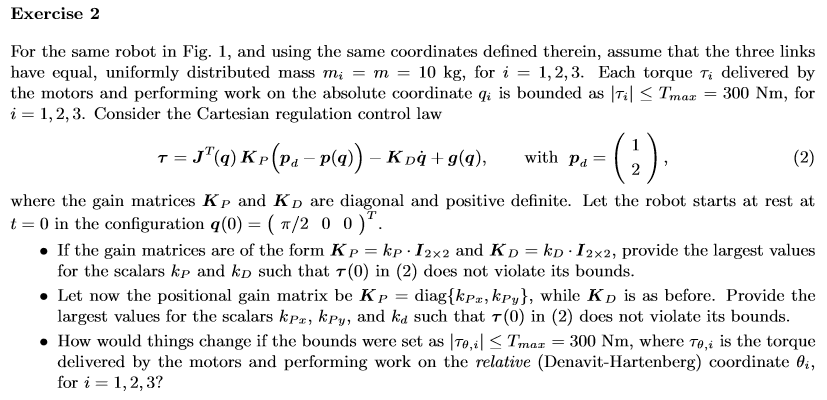

% Same parameters as above
g = [0 g0 0].' 

$$g = \left(\begin{array}{c} 0\\ g_{0}\\ 0 \end{array}\right)$$


[g_q,PE,U] = getGravityWithJacobian(dhTable,q,l,m,d,g,0)

*** Computation of Potential Energy (Jacobian-based method) 


$$g\_q = \left(\begin{array}{c} d_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)+g_{0}\,l_{1}\,m_{2}\,\cos\left(q_{1}\right)+g_{0}\,l_{1}\,m_{3}\,\cos\left(q_{1}\right)\\ d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right)+g_{0}\,l_{2}\,m_{3}\,\cos\left(q_{2}\right)\\ d_{3}\,g_{0}\,m_{3}\,\cos\left(q_{3}\right) \end{array}\right)$$

$$PE = g_{0}\,m_{3}\,\left(d_{3}\,\sin\left(q_{3}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{2}\,\sin\left(q_{2}\right)\right)+g_{0}\,m_{2}\,\left(d_{2}\,\sin\left(q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

U = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


for i = 1:n
    U{i} % To see the sub results
end

$$ans = d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

$$ans = g_{0}\,m_{2}\,\left(d_{2}\,\sin\left(q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)$$

$$ans = g_{0}\,m_{3}\,\left(d_{3}\,\sin\left(q_{3}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{2}\,\sin\left(q_{2}\right)\right)$$

% l = 1, d = 0.5

g_q = subs(g_q,[l;d],[ones([n,1]);0.5*ones([n,1])])

$$g\_q = \left(\begin{array}{c} \frac{g_{0}\,m_{1}\,\cos\left(q_{1}\right)}{2}+g_{0}\,m_{2}\,\cos\left(q_{1}\right)+g_{0}\,m_{3}\,\cos\left(q_{1}\right)\\ \frac{g_{0}\,m_{2}\,\cos\left(q_{2}\right)}{2}+g_{0}\,m_{3}\,\cos\left(q_{2}\right)\\ \frac{g_{0}\,m_{3}\,\cos\left(q_{3}\right)}{2} \end{array}\right)$$

syms tau kp

*** Computation of Kinetic Energy (Jacobian-based method) 


T = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


$$M = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+{d_{1}}^{2}\,m_{1}+{d_{2}}^{2}\,m_{2}+{d_{3}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{3}+2\,d_{2}\,l_{1}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)+2\,d_{3}\,l_{1}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)+2\,d_{3}\,l_{2}\,m_{3}\,\cos\left(q_{2}-q_{3}\right)+2\,l_{1}\,l_{2}\,m_{3}\,\cos\left(q_{1}-q_{2}\right) & \sigma_{3} & \sigma_{1}\\ \sigma_{3} & m_{2}\,{d_{2}}^{2}+m_{3}\,{d_{3}}^{2}+\sigma_{4}+m_{3}\,{l_{2}}^{2}+I_{2}+I_{3} & \sigma_{2}\\ \sigma_{1} & \sigma_{2} & m_{3}\,{d_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{3}+{d_{3}}^{2}\,m_{3}+d_{3}\,l_{1}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)+d_{3}\,l_{2}\,m_{3}\,\cos\left(q_{2}-q_{3}\right)\\ \sigma_{2}=m_{3}\,{d_{3}}^{2}+l_{2}\,m_{3}\,\cos\left(q_{2}-q_{3}\right)\,d_{3}+I_{3}\\ \sigma_{3}=m_{2}\,{d_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{1}-q_{2}\right)\,d_{2}+m_{3}\,{d_{3}}^{2}+\sigma_{4}+l_{1}\,m_{3}\,\cos\left(q_{1}-q_{3}\right)\,d_{3}+m_{3}\,{l_{2}}^{2}+l_{1}\,m_{3}\,\cos\left(q_{1}-q_{2}\right)\,l_{2}+I_{2}+I_{3}\\ \sigma_{4}=2\,m_{3}\,\cos\left(q_{2}-q_{3}\right)\,d_{3}\,l_{2} \end{array}$$

% Define control law
% etc etc etc ... eso sale...
tau = kp*J.'

### Exercise 2

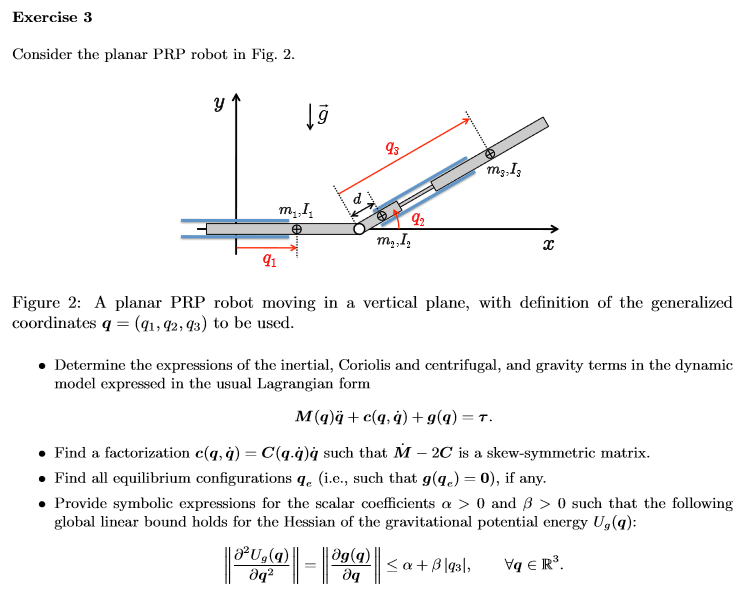

clear;clc
sigma = [1;0;1] % 0: Revolute, 1: Prismatic

sigma =      1
     0
     1


n = length(sigma); %Number of joints

q = sym('q', [n 1]);
qd = sym('qd',[n 1]);
qdd = sym('qdd',[n 1]);
d = sym('d', [n 1]);
a = sym('a', [n 1]);
l = sym('l',[n 1]);
d = sym('d',[n 1]);
m = sym('m',[n 1]);
I = sym('I',[n 1]);
syms g0
g = [0 -g0 0].' 

$$g = \left(\begin{array}{c} 0\\ -g_{0}\\ 0 \end{array}\right)$$


% alpha,a, d, theta
% Absolute coordinates 
dhTable = [-pi/2 0 q(1) 0;
           0 d(2) 0 q(2);
           pi/2 0 q(3)+d(2) 0]

$$dhTable = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & q_{1} & 0\\ 0 & d_{2} & 0 & q_{2}\\ \frac{\pi }{2} & l_{2} & q_{3} & 0 \end{array}\right)$$

[KE,T] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,0)

*** Computation of Kinetic Energy (Jacobian-based method) 


$$KE = \frac{I_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{3}}^{2}}{2}+\frac{{d_{2}}^{2}\,m_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{{d_{2}}^{2}\,m_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{{l_{2}}^{2}\,m_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+d_{2}\,l_{2}\,m_{3}\,{{\mathrm{qd}}_{2}}^{2}-d_{2}\,m_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)-d_{2}\,m_{3}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)-l_{2}\,m_{3}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}\,\cos\left(q_{2}\right)$$

T = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}



% Wrong. The best approach here is to define the positions one by one, and take the derivatives, as

$$ans = {{\mathrm{qd}}_{1}}^{2}\,m_{1}$$

$$ans = \left({d_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}-2\,\cos\left(q_{2}\right)\,d_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{{\mathrm{qd}}_{1}}^{2}\right)\,m_{2}+I_{2}\,{{\mathrm{qd}}_{2}}^{2}$$

$$ans = \left({d_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}+2\,d_{2}\,l_{2}\,{{\mathrm{qd}}_{2}}^{2}-2\,\cos\left(q_{2}\right)\,d_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{l_{2}}^{2}\,{{\mathrm{qd}}_{2}}^{2}-2\,\cos\left(q_{2}\right)\,l_{2}\,{\mathrm{qd}}_{1}\,{\mathrm{qd}}_{2}+{{\mathrm{qd}}_{1}}^{2}+{{\mathrm{qd}}_{3}}^{2}\right)\,m_{3}+I_{3}\,{{\mathrm{qd}}_{2}}^{2}$$

% shown in the solutions.